# Perform Two-Way ANOVA

This example shows how to perform two-way ANOVA to determine the effect of car model and factory on the mileage rating of cars.

Load and display the sample data.

load mileage
mileage

mileage =    33.3000   34.5000   37.4000
   33.4000   34.8000   36.8000
   32.9000   33.8000   37.6000
   32.6000   33.4000   36.6000
   32.5000   33.7000   37.0000
   33.0000   33.9000   36.7000


There are three car models (columns) and two factories (rows). The data has six mileage rows because each factory provided three cars of each model for the study (i.e., the replication number is three). The data from the first factory is in the first three rows, and the data from the second factory is in the last three rows.

Perform two-way ANOVA. Return the structure of statistics, `stats`, to use in multiple comparisons.

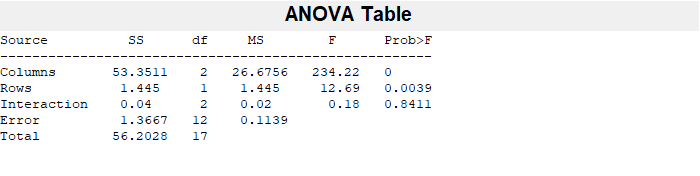

nmbcars = 3; % Number of cars from each model, i.e., number of replications
[~,~,stats] = anova2(mileage,nmbcars);

You can use the *F*-statistics to do hypotheses tests to find out if the mileage is the same across models, factories, and model - factory pairs. Before performing these tests, you must adjust for the additive effects. `anova2` returns the *p*-value from these tests.

The *p*-value for the model effect (`Columns`) is zero to four decimal places. This result is a strong indication that the mileage varies from one model to another.

The *p*-value for the factory effect (`Rows`) is 0.0039, which is also highly significant. This value indicates that one factory is out-performing the other in the gas mileage of the cars it produces. The observed *p*-value indicates that an *F*-statistic as extreme as the observed *F* occurs by chance about four out of 1000 times, if the gas mileage were truly equal from factory to factory.

The factories and models appear to have no interaction. The *p*-value, 0.8411, means that the observed result is likely (84 out of 100 times), given that there is no interaction.

Perform [multiple comparisons](docid:stats_ug.bum2f3y-1) to find out which pair of the three car models is significantly different.

Note: Your model includes an interaction term.  A test of main effects can be 
difficult to interpret when the model includes interactions.


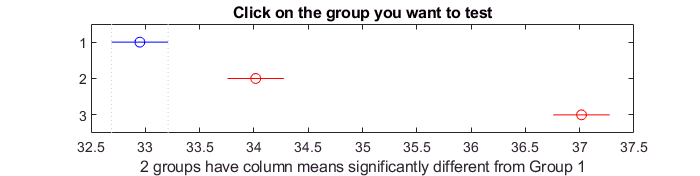

c =     1.0000    2.0000   -1.5865   -1.0667   -0.5469    0.0004
    1.0000    3.0000   -4.5865   -4.0667   -3.5469    0.0000
    2.0000    3.0000   -3.5198   -3.0000   -2.4802    0.0000


c = multcompare(stats)

In the matrix `c`, the first two columns show the pairs of car models that are compared. The last column shows the *p*-values for the test. All *p*-values are small (0.0004, 0, and 0), which indicates that the mean mileage of all car models are significantly different from each other. 

In the figure, the blue bar is the comparison interval for the mean mileage of the first car model. The red bars are the comparison intervals for the mean mileage of the second and third car models. None of the second and third comparison intervals overlap with the first comparison interval, indicating that the mean mileage of the first car model is different from the mean mileage of the second and the third car models. If you click on one of the other bars, you can test for the other car models. None of the comparison intervals overlap, indicating that the mean mileage of each car model is significantly different from the other two.

*Copyright 2015 The MathWorks, Inc.*